# Eksamensæt - F22

**M3NUM1 Anvendte Numeriske Metoder -- 16-01-2023**

**Mathias Bruun Houmøller -- 202006837 -- Au666097**

## Opgave 1

clear
format short %formater resultater til 4 decimaler
u = symunit; %Laver symbolske si enheder
% separateUnits(x)
% class(double(b))
% unitConvert(expr,units)

### 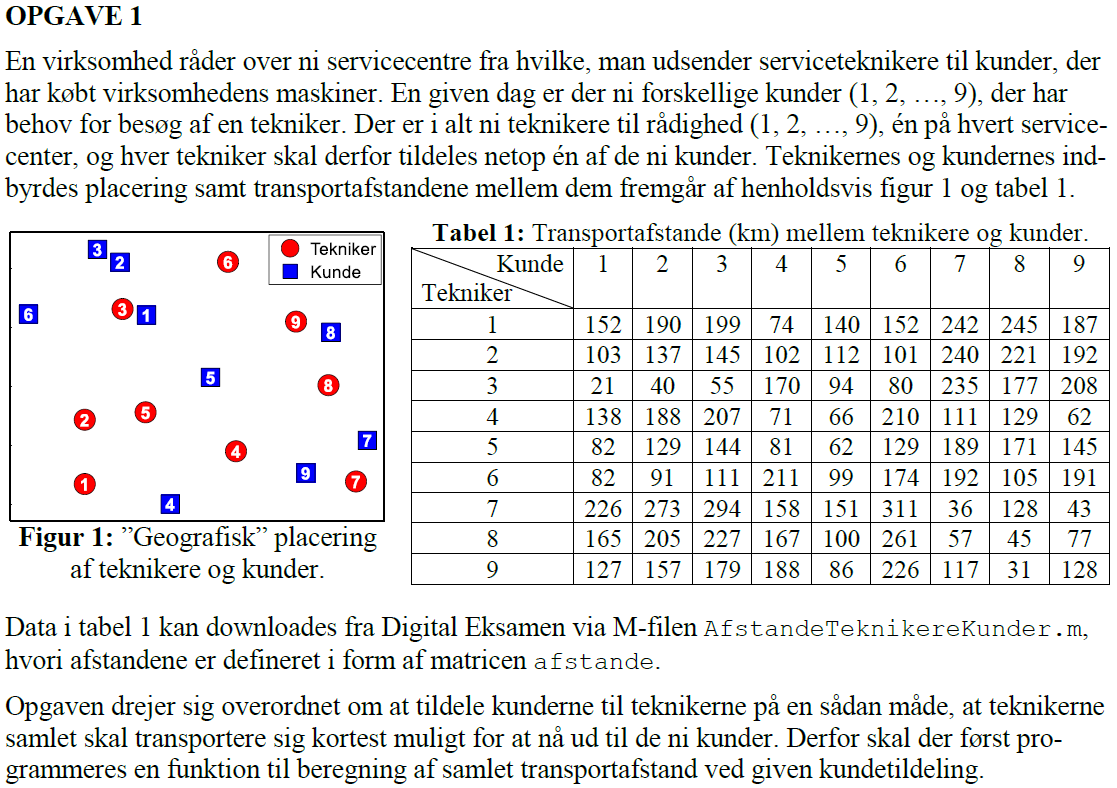

### (1a)

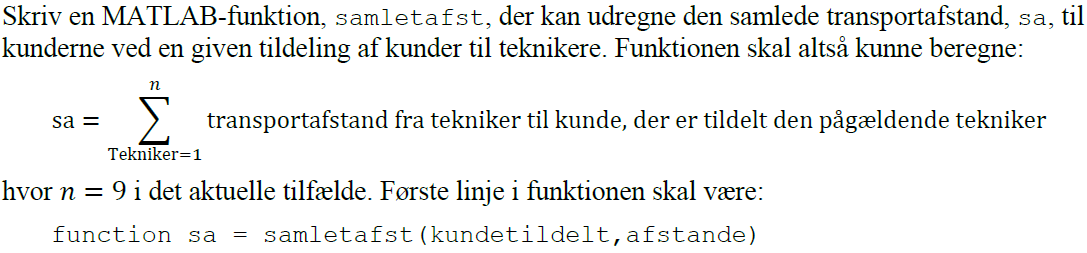

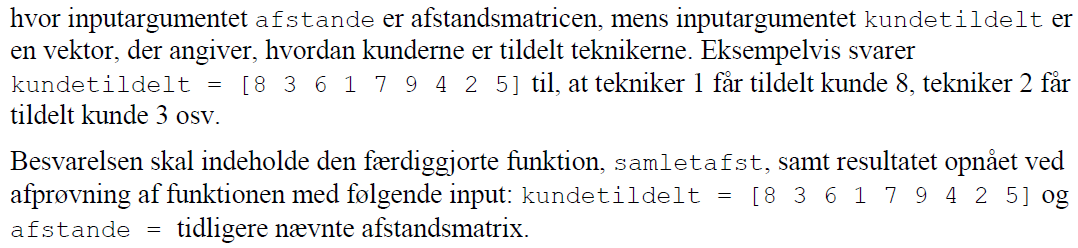

% afstande = [152 190 199  74 140 152 242 245 187
%             103 137 145 102 112 101 240 221 192
%              21  40  55 170  94  80 235 177 208
%             138 188 207  71  66 210 111 129  62
%              82 129 144  81  62 129 189 171 145
%              82  91 111 211  99 174 192 105 191
%             226 273 294 158 151 311  36 128  43
%             165 205 227 167 100 261  57  45  77
%             127 157 179 188  86 226 117  31 128];
AfstandeTeknikereKunder; %henter matrixen afstande fra m filen.
kundetildelt = [8 3 6 1 7 9 4 2 5];

sa = samletafst(kundetildelt,afstande)

sa = 1437

Den samlede transport imellem teknikker og tildelte kunder er således 1437 km

### (1b)

AfstandeTeknikereKunder; % Definér afstandsmatricen afstande
n = length(afstande);
tildelingsmuligh = perms(1:n); % Generér alle tildelingsmuligheder
N = factorial(n); % Antal tildelingsmuligheder = n!
minsamletafstand = +inf; % Sæt initielt min. afst. = uendelig

for i = 1:N 
    kundetildelt = tildelingsmuligh(i,:);
    samletafstand = samletafst(kundetildelt,afstande);
    if samletafstand < minsamletafstand && kundetildelt(1) ~= 4 && kundetildelt(4) == 7
        optkundetildelt = kundetildelt;
        minsamletafstand = samletafstand;
    end
end
optkundetildelt % Vis indhold af optkundetildelt

optkundetildelt =      1     6     3     7     4     2     9     8     5


minsamletafstand % Vis værdi af minsamletafstand

minsamletafstand = 765

## Opgave 2

clear
u = symunit;

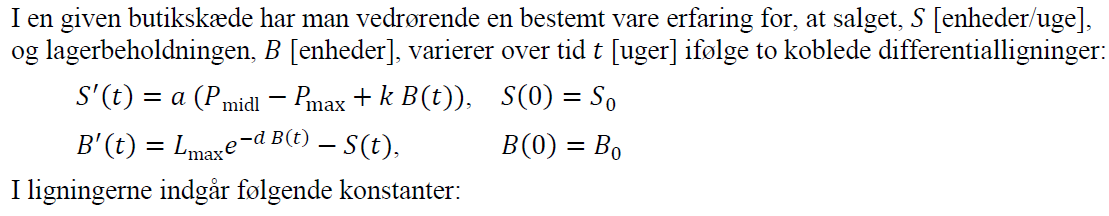

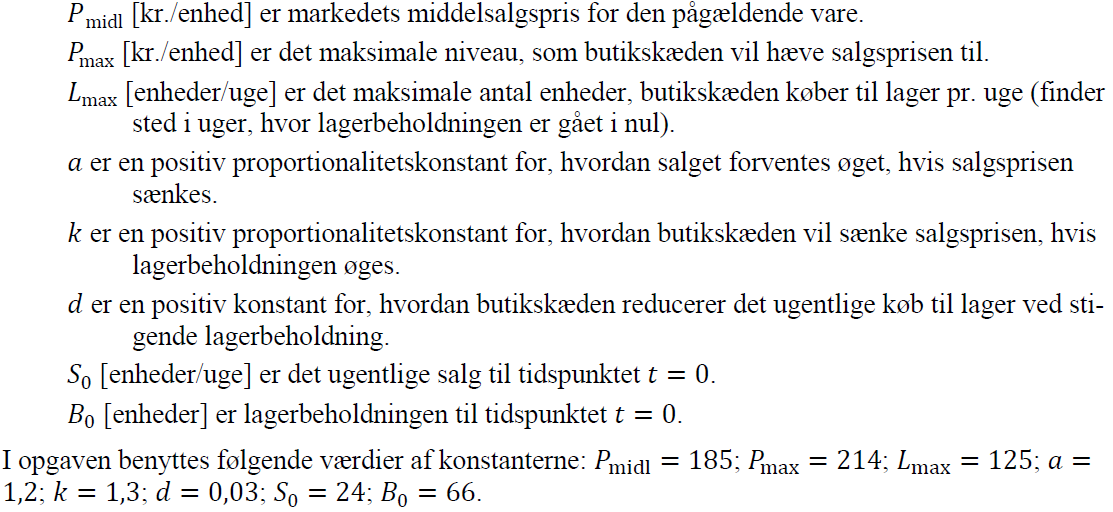

### (2a)

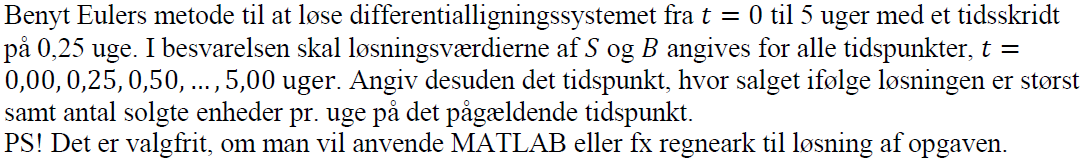

Pmidl = 185; 
Pmax = 214; 
Lmax = 125; 
a = 1.2; 
k = 1.3; 
d = 0.03; 
S0 = 24; 
B0 = 66; 

dYdt = @(t,Y) [a*(Pmidl - Pmax + k*Y(2)), Lmax*exp(-d*Y(2)) - Y(1)]; 
Y0 = [S0 B0]; 
tidsinterval = [0 5]; 
h = 0.25; 
[t,Y] = eulsys(dYdt,tidsinterval,Y0,h); 
S = Y(:,1); 
B = Y(:,2); 

disp(table(t,S,B,'VariableNames',{'t, uger','S, enh./uge','B, enh.'}))

    t, uger    S, enh./uge    B, enh.
    _______    ___________    _______

        0            24           66 
     0.25         41.04       64.315 
      0.5        57.423       58.593 
     0.75        71.574       49.626 
        1        82.228       38.784 
     1.25        88.654       27.989 
      1.5        90.869       19.321 
     1.75        89.704       14.107 
        2        86.506       12.148 
     2.25        82.544       12.227 
      2.5        78.612       13.246 
     2.75        75.078       14.595 
        3         72.07       15.995 
     3.25        69.608       17.317 
      3.5        67.662       18.503 
     3.75        66.178       19.526 
        4        65.093       20.377 
     4.25         64.34       21.061 
      4.5        63.854       21.589 
     4.75        63.574       21.978 
        5        63.445       22.247 



salg = max(S)

salg =        90.869


result_t = find(S==max(S))

result_t =      7


salg_t = t(result_t)

salg_t =           1.5


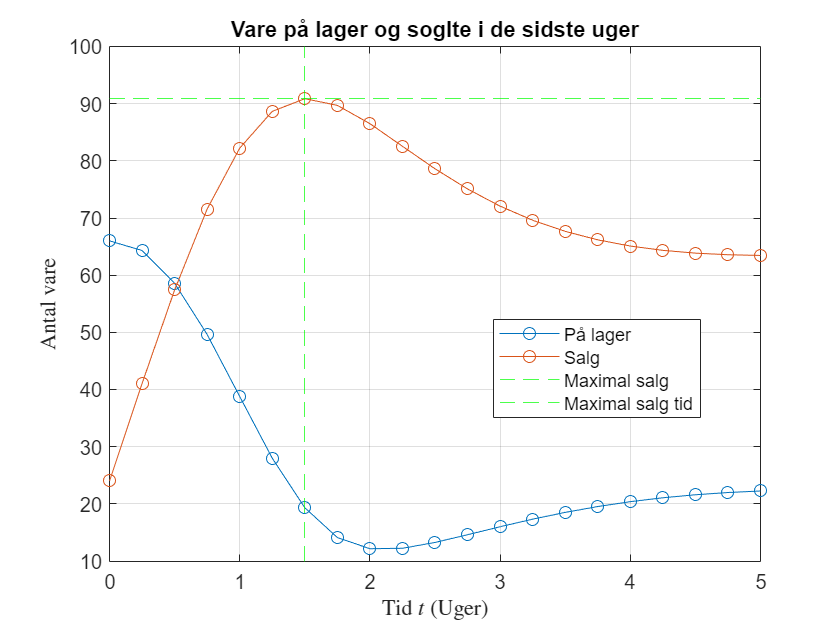


% der plottes
plot(t,B,'-o', 'DisplayName', 'På lager') %data plottes
hold on
plot(t,S,'-o', 'DisplayName', 'Salg') % interpolation med spline plottes
yline(max(S), 'g--', 'DisplayName', 'Maximal salg')
xline(t(result_t), 'g--', 'DisplayName', 'Maximal salg tid')

% formalier
legend('location', 'best')
title('Vare på lager og soglte i de sidste uger')
xlabel('Tid $t$ (Uger)', 'interpreter', 'latex')
ylabel('Antal vare', 'interpreter', 'latex')
grid
hold off

**Vi får således at salget er størst efter 1,5 uger hvor der sælges 90,87 enheder**

### (2b)

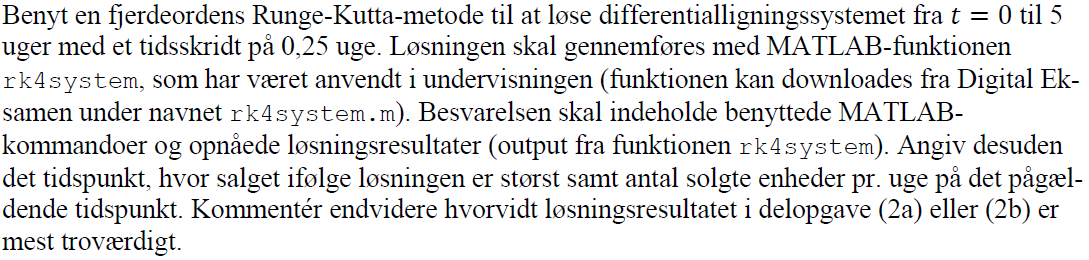


[t,Y] = rk4system(dYdt,tidsinterval,Y0,h);
S = Y(:,1); 
B = Y(:,2); 
disp(table(t,S,B,'VariableNames',{'t, uger','S, enh./uge','B, enh.'}))

    t, uger    S, enh./uge    B, enh.
    _______    ___________    _______

        0            24           66 
     0.25         40.46       62.428 
      0.5        54.885       55.741 
     0.75        66.295       47.196 
        1        74.248       38.261 
     1.25        78.869         30.3 
      1.5        80.728       24.191 
     1.75         80.61       20.151 
        2        79.276       17.883 
     2.25        77.323       16.897 
      2.5         75.16       16.735 
     2.75        73.037       17.054 
        3        71.094       17.626 
     3.25        69.399       18.303 
      3.5        67.972       18.996 
     3.75        66.811       19.653 
        4        65.893       20.244 
     4.25         65.19       20.755 
      4.5        64.671       21.182 
     4.75        64.301       21.527 
        5        64.052       21.798 



salg = max(S)

salg =        80.728


result_t = find(S==max(S))

result_t =      7


salg_t = t(result_t)

salg_t =           1.5


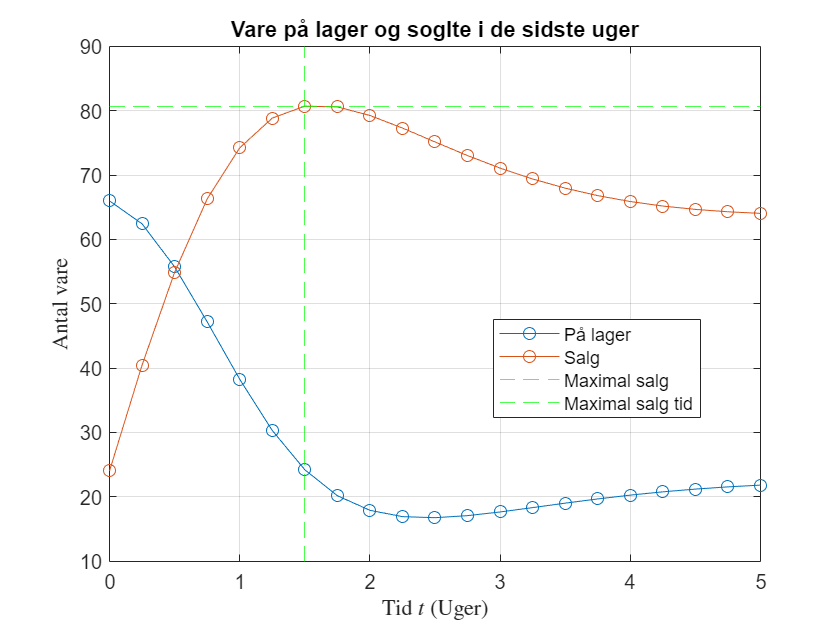

% der plottes
plot(t,B,'-o', 'DisplayName', 'På lager') %data plottes
hold on
plot(t,S,'-o', 'DisplayName', 'Salg') % interpolation med spline plottes
yline(max(S), 'g--', 'DisplayName', 'Maximal salg')
xline(t(result_t), 'g--', 'DisplayName', 'Maximal salg tid')

% formalier
legend('location', 'best')
title('Vare på lager og soglte i de sidste uger')
xlabel('Tid $t$ (Uger)', 'interpreter', 'latex')
ylabel('Antal vare', 'interpreter', 'latex')
grid
hold off

**Der er således solgt flest enheder efter 1,5 uger hvor der sælges 80,73 enheder**

**Da Euler metoden bruger tangent heldningen ved hvert punkt til at finde det næst bliver den mere præcis mere mange punkter.**

**Her har vi dog relativt få punkter og den vil derfor være mindre pålidelig (https://www.geogebra.org/m/kktsp4gx)**

**Hvor fjerdeordens Runge-Kutta-metode tager højde for de sidste 4 punkter og dermed får en mere præcis fremskrivning.**

**( https://denstoredanske.lex.dk/differentialligning_(numerisk_l%C3%B8sning) )**

Fra løsnings forslaget:

Da Eulers metode og den fjerdeordens Runge-Kutta-metode begge er gennemført med tidsskridt på 0,25 uge, vil løsningen fundet med sidstnævnte metode (delopgave (2a)) være mest troværdigt. Det skyldes, at en fjerdeordensmetoden må antages at være mere nøjagtig end en førsteordensmetode (Eulers metode).

## Opgave 3

clear
u = symunit;

### (3a)

Jacobi-matricen bestemmes ved partiel differentiation af de enkelte funktioner mht. hver enkelte ube-kendte:

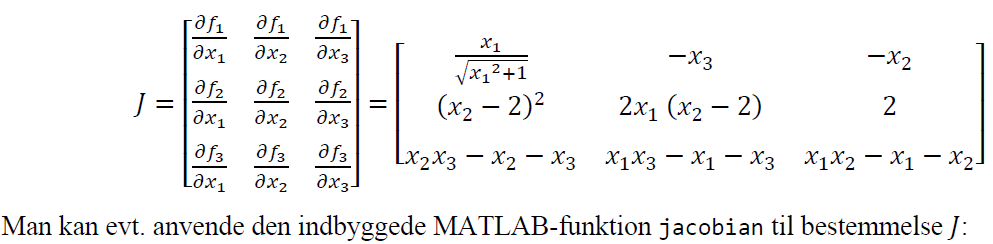

syms x_1 x_2 x_3 f J 

f = [sqrt(x_1^2+1) - x_2*x_3 - 2
    x_1*(x_2-2)^2 + 2*x_3 - 2
    x_1*x_2*x_3 - x_1*x_2 - x_1*x_3 - x_2*x_3] 

$$f = \left(\begin{array}{c} \sqrt{{x_{1}}^{2}+1}-x_{2}\,x_{3}-2\\ 2\,x_{3}+x_{1}\,{\left(x_{2}-2\right)}^{2}-2\\ x_{1}\,x_{2}\,x_{3}-x_{1}\,x_{3}-x_{2}\,x_{3}-x_{1}\,x_{2} \end{array}\right)$$

J = jacobian(f,[x_1;x_2;x_3])

$$J = \left(\begin{array}{ccc} \frac{x_{1}}{\sqrt{{x_{1}}^{2}+1}} & -x_{3} & -x_{2}\\ {\left(x_{2}-2\right)}^{2} & x_{1}\,\left(2\,x_{2}-4\right) & 2\\ x_{2}\,x_{3}-x_{3}-x_{2} & x_{1}\,x_{3}-x_{3}-x_{1} & x_{1}\,x_{2}-x_{2}-x_{1} \end{array}\right)$$

**Da der er matrixelementer i Jacobi-matricen, der ikke er konstante, fordi de afhænger af de ube-kendte, kan man konkludere, at ligningssystemet er ulineært.**

Eller man kan se at når man differentier ligningerne for man forskelleige man ikke kun konstanter

for i = 1:length(f)
    fprintf(" Ligning %d patielt differentiert for alle varable", i)
    diff(f(i), x_1)
    diff(f(i), x_2)
    diff(f(i), x_3)
end

 Ligning 1 patielt differentiert for alle varable

$$ans = \frac{x_{1}}{\sqrt{{x_{1}}^{2}+1}}$$

$$ans = -x_{3}$$

$$ans = -x_{2}$$

 Ligning 2 patielt differentiert for alle varable

$$ans = {\left(x_{2}-2\right)}^{2}$$

$$ans = x_{1}\,\left(2\,x_{2}-4\right)$$

$$ans = 2$$

 Ligning 3 patielt differentiert for alle varable

$$ans = x_{2}\,x_{3}-x_{3}-x_{2}$$

$$ans = x_{1}\,x_{3}-x_{3}-x_{1}$$

$$ans = x_{1}\,x_{2}-x_{2}-x_{1}$$

Det ses at ligninerne ikke bliver til konstanter efter differentiering og de er altså ikke lineær.

### (3b)

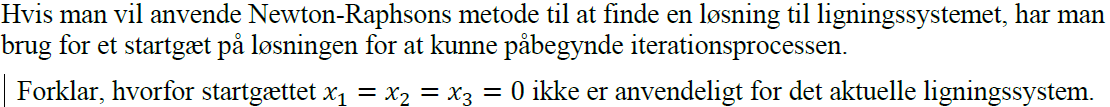

Da jacobian matricen bliver

J_calc = [0 0 0; 4 0 2; 0 0 0]

J_calc =      0     0     0
     4     0     2
     0     0     0


J_alt = [-1 -1 -2
        0 0 0
        -6 -3 -9]

J_alt =     -1    -1    -2
     0     0     0
    -6    -3    -9


det(J_calc)

ans =      0


det(J_alt)

ans =      0


**Da determinanten bliver 0 kan vi ikke invertere matrixen og Newton-Raphsons metode kan således ikke bruges**

### (3c)

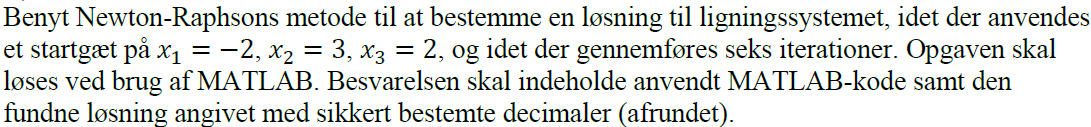

clear
x_1 = -2;
x_2 = 3;
x_3 = 2;
X = [x_1; x_2; x_3]; %vektor

maxit = 6;

format long 
x = [-2; 3; 2];
for i = 1:maxit 
    f = [sqrt(x(1)^2+1) - x(2)*x(3) - 2
        x(1)*(x(2)-2)^2 + 2*x(3) - 2
        x(1)*x(2)*x(3) - x(1)*x(2) - x(1)*x(3) - x(2)*x(3)];

    J = [x(1)/sqrt(x(1)^2+1) -x(3) -x(2)
        (x(2)-2)^2 2*x(1)*(x(2)-2) 2
        x(2)*x(3)-x(2)-x(3) x(1)*x(3)-x(1)-x(3) x(1)*x(2)-x(1)-x(2)]; 
    fprintf('Interation %d', i)
    x = x - J\f 
end

Interation 1

x =   -3.583715866413271
   2.159626588952238
   1.111111111111111


Interation 2

x =   -5.428534915600491
   2.666146263618940
   1.358919084389606


Interation 3

x =   -5.020999340936641
   2.437310211818899
   1.286519818697206


Interation 4

x =   -4.924247604183617
   2.352918362594540
   1.285555024186328


Interation 5

x =   -4.915860578084753
   2.342369360058020
   1.287805924341830


Interation 6

x =   -4.915772917325267
   2.342223345196957
   1.287859784253214


Iteration 5 og 6 er ens med op til 3 decimaler


$$x_1 = 4,916 \\ x_2 = 2,342 \\ x_3 = 1,288$$


Hvor der er brugt 6 iterationer.

Man kan også løse opgaven som

format long 
x0 = [-2; 3; 2]; 
es = 0.000001; 
maxit = 6; 
[x,f,ea,iter] = newtmult(@Jogf,x0,es,maxit) 

x =   -4.915772917325267
   2.342223345196957
   1.287859784253214


f = 1.0e-03 *

   0.024022435512361
  -0.609492849895421
   0.140747104591110


ea =    0.006234028081150


iter =      6


xinterval = [x-x*ea/100 x+x*ea/100]

xinterval =   -4.915466466661195  -4.916079367989338
   2.342077330335894   2.342369360058020
   1.287779498712618   1.287940069793810


clear
x_1 = -2;
x_2 = 3;
x_3 = 2;
X = [x_1; x_2; x_3]; %vektor
maxit = 6;
es = 0.0001;
iter = 0;

while 1 
    %resultatet af hver ligning sættes = 0
    f = [sqrt(x_1^2+1) - x_2*x_3 - 2
    x_1*(x_2-2)^2 + 2*x_3 - 2
    x_1*x_2*x_3 - x_1*x_2 - x_1*x_3 - x_2*x_3];

    % de afledte funktioner indsættes i en matrix
    J = [x_1/sqrt(x_1^2 + 1), -x_3, -x_2
        (x_2 - 2)^2, x_1*(2*x_2 - 4), 2
        x_2*x_3 - x_3 - x_2, x_1*x_3 - x_3 - x_1, x_1*x_2 - x_2 - x_1];

    dX = J\f; %løser ligningsystemet J*dx = f
    X = X - dX;
    iter = iter + 1;
    ea = 100*max(abs(dX./X));
    if iter >= maxit || ea <= es, break, end
end

x1 = X(1)

x1 =  -11.502295198479628


x2 = X(2)

x2 =   -2.042240466286573


x3 = X(3)

x3 =   -3.333333333333333


ea

ea =   41.149581791209037


iter

iter =      6


## Plot koder

%der plottes
% plot(t,y,'o', 'DisplayName', 'Data') %data plottes
% hold on
% plot(tt,ned_spl_cub, 'DisplayName', 'interpolation') % interpolation med spline plottes
% 
% % formalier
% legend('location', 'best')
% title('Spline interpolation af data')
% xlabel('$x$ (Dag)', 'interpreter', 'latex')
% ylabel('Akkumulerde nedbor $y$ (mm)', 'interpreter', 'latex')
% grid
% hold off

## Functioner

function [J,f] = Jogf(x) 
    f = [sqrt(x(1)^2+1) - x(2)*x(3) - 2 
        x(1)*(x(2)-2)^2 + 2*x(3) - 2 
        x(1)*x(2)*x(3) - x(1)*x(2) - x(1)*x(3) - x(2)*x(3)]; 
    J = [x(1)/sqrt(x(1)^2+1) -x(3) -x(2) 
        (x(2)-2)^2 2*x(1)*(x(2)-2) 2 
        x(2)*x(3)-x(2)-x(3) x(1)*x(3)-x(1)-x(3) x(1)*x(2)-x(1)-x(2)];
end
